3. Reprezentati pe acelasi grafic $f$ si $L_mf$. 

syms x;
f = x+sqrt(abs(x))*sin(x+sqrt(abs(sin(x))));

nodes = [-2 0 1 2 3 4 5 6];
node_vals = double(subs(f,x,nodes));

m = size(nodes,2)

m = 8

poly = LagrangeClassicPoly(nodes, node_vals)

poly =    -0.0049    0.0777   -0.4139    0.7119    0.8436   -4.2101    4.9364         0


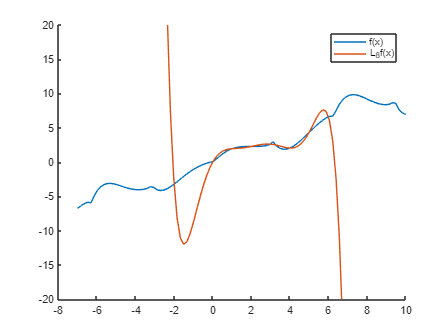


hold on
t = linspace(-7,10,100);
plot(t, double(subs(f,x,t)),"DisplayName","f(x)")           
plot(t, polyval(poly,t),"DisplayName",sprintf("L_{%i}f(x)",m))           
legend
ylim([[-20 20]])
hold off

Functie care returneaza fundamental $L_k(x) = \prod_{j=1, j\neq k}^m \frac{x-x_j}{x_k-x_j}$, unde $x_1, \ldots, x_n$ sunt noduri.

function lk = L(nodes,k)
    % polinomul fundamental L_k pentru nodurile nodes_1,...,nodes_n       
    % lk = prod_{j,j!=k}(x-xj)/prod_{j,j!=k}(xk-xj)
    m = size(nodes,2);
    roots = cat(2, nodes(1:k-1), nodes(k+1:m));    
    p = poly(roots);
    lk = p ./ polyval(p,nodes(k));
end

Functie de calcul a valorilor unor puncte date $t_1,\ldots,t_n$ cunoscand valorile functiei $f$ in nodurile $x_1,\ldots,x_m$.

Polinomul care apropximeaza functia este


$$p_f(t)=\sum_{k=1}^^m(L_k(t)\cdot f(x_k))=\sum_{k=1}^^m(L_k(t)\cdot y_k)$$


function pf = LagrangeClassicPoly(x,y)
    m = size(x,2);    
    pf = zeros('like', x);
    for k=1:m                       
        pf = pf + (L(x,k) .* y(k));
    end          
end

function u = LagrangeClassic(x,y, t)
    u = polyval(LagrangeClassicPoly(x,y),t);
end